# **sBAXTER**

# PLANEACIÓN DE TRAYECTORIAS

## **CINÉMATICA DIRECTA**

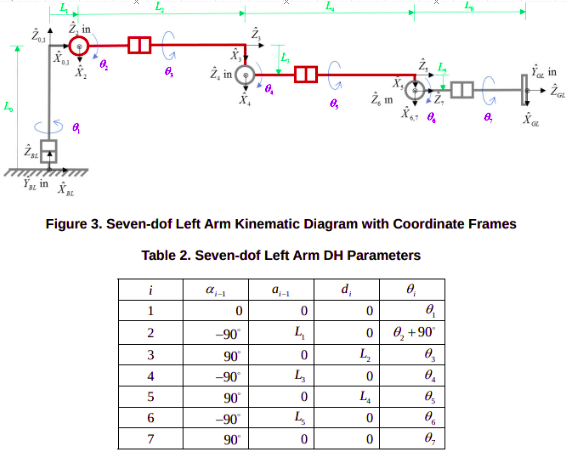

Ejemplo de la matriz de posicion en la cual los valores de X,Y ,Z ya son declarados por lo cual

se puede despejar los valores de th2 y th4

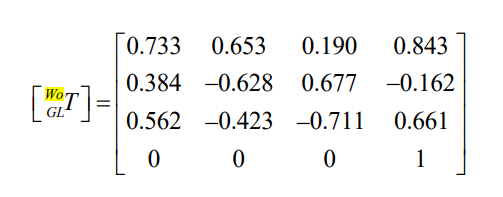


%%%en m
l0=270.35/1000

l0 = 0.2704

l1=69/1000;
l2=364.35/1000;
l3=364.35/1000;
l4=374.29/1000;
l5=10/1000;
l6=368.30/1000;
L=278/1000;
h=64/1000;
H=1104/1000;
%%"en cinematica directa" primero se proporciona una matriz de
%%transfomracion desde wo(centro) hasta G(manipulador) la cual se debe
%%transformar a una matriz de transformacion de los grados de libertad

TwoGL=[0.733 0.653 0.190 0.843;0.384 -0.628 0.677 -0.162;0.562 -0.423 -0.711 0.661;0 0 0 1]
%%TwoGL=[0.566 0.674 0.475 1.026;-0.021 -0.564 0.825 0.039;0.824 -0.477 -0.306 0.788;0 0 0 1]
TwoBL=[sqrt(2)/2 sqrt(2)/2 0 h; -sqrt(2)/2 sqrt(2)/2 0 -H; 0 0 1 L; 0 0 0 1];
%TwoBR=[-sind(45) cosd(45) 0 -L;-sind(45) -sind(45) 0 -h;0 0 1 H;0 0 0 1];
T6Gl=[1 0 0 0; 0 1 0 0; 0 0 1 l6; 0 0 0 1];
TBlO=[1 0 0 0; 0 1 0 0; 0 0 1 l0; 0 0 0 1];
TWoO=TwoBL*TBlO;
T0t6=inv(TWoO)*TwoGL*inv(T6Gl)

T0t6 =     0.2468    0.9058   -0.3444    0.0116
    0.7898    0.0177    0.6131    0.9911
    0.5620   -0.4230   -0.7110    0.3745
         0         0         0    1.0000



%%%%%%%%%%%%%%%%tomando los valores de ejemplo de la matriz
x=T0t6(1,4)

x = 0.0116

y=T0t6(2,4)

y = 0.9911

z=T0t6(3,4)
Th1= atan2((y),(x)) %%% ya que tecnicamente seria atan2(Sin(th1),cos(th1)) segun el despeje, sin embargo

Th1 = 1.5591

                  %%% solo nos estarian dando el valor de th1 sino solo los
                  %%% resutaldos de sin y cos o usando los valores de x y y
                  %%% que contienen th1%%%%%%%%%%%el resultado es en
                  %%% radianes
                
lh=sqrt(l2^2+l3^2);
E=2*lh*(l1-x/cos(Th1));%% ni idea de que hago con x con esta variable

Unrecognized function or variable 'l1'.

F=2*lh*z;
G=((x^2)/(cosd(Th1)^2))+l1^2+lh^2-l4^2+z^2-2*(l1*x/cosd(Th1));
%%%%%%%%%%%%del libro
Th2_1=2*atan((-F+sqrt(E^2+F^2-G^2))/(G-E))
Th2_2=2*atan((-F-sqrt(E^2+F^2-G^2))/(G-E))%%%codo abajo

Th3=0;

Th4_1=atan2((-z-lh*sin(Th2_1)),((x/cos(Th1)-l1-lh-lh*cos(Th2_1))))
Th4_2=atan2((-z-lh*sin(Th2_2)),((x/cos(Th1)-l1-lh-lh*cos(Th2_2))))%%%codo abajo
%%%%%%%%%%%%%%%%%%obtener R3to6
for i=1:3
    for j=1:3
    Ro06(i,j)=T0t6(i,j);
    end
end
R03CA=[-cos(Th1)*sin(Th2_2+Th4_2) -cos(Th1)*cos(Th2_2+Th4_2) ;
       -sin(Th1)*sin(Th2_2+Th4_2) -sin(Th1)*cos(Th2_2+Th4_2) ;
       -cos(Th2_2+Th4_2)           sin(Th2_1+Th4_1)           ];
R03CB=[-cos(Th1)*sin(Th2_2+Th4_2) -cos(Th1)*cos(Th2_2+Th4_2) ;
       -sin(Th1)*sin(Th2_2+Th4_2) -sin(Th1)*cos(Th2_2+Th4_2) ;
       -cos(Th2_2+Th4_2)           sin(Th2_2+Th4_2)           ];

R3t06CA=transpose(R03CA)*Ro06;
R3t06CB=inv(R03CB)*Ro06;

%%%%%%%%%%%%%%%%%%
Th5_1=atan2(R3t06CA(3,3),R3t06CA(1,3))

Th7_1=atan2(-R3t06CA(2,2),R3t06CA(2,1)) 
Th6_1=atan2(R3t06CA(2,1)/cos(Th7),-R3t06CA(2,3))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Th5_2=atan2(R3t06CB(3,3),R3t06CB(1,3))

Th7_2=atan2(-R3t06CB(2,2),R3t06CB(2,1)) 
Th6_2=atan2(R3t06CB(2,1)/cos(Th7),-R3t06CB(2,3))